clc

Strain = XTCControlIndentation.VarName1

Strain =    22.3424
   22.3120
   22.2774
   22.2504
   22.2192
   22.1902
   22.1487
   22.1182
   22.0954
   22.0497


Xdiff = XTCControlIndentation.VarName3

Xdiff =     0.0210
    0.0198
    0.0198
    0.0207
    0.0207
    0.0207
    0.0204
    0.0201
    0.0207
    0.0198


Ydiff = XTCControlIndentation.VarName5

Ydiff =     0.0223
    0.0220
    0.0220
    0.0217
    0.0220
    0.0223
    0.0230
    0.0217
    0.0227
    0.0217


Sum = XTCControlIndentation.VarName7

Sum =     0.0702
    0.0699
    0.0708
    0.0696
    0.0699
    0.0699
    0.0702
    0.0699
    0.0696
    0.0708


SpringConst = 0.32

SpringConst = 0.3200


smooth_Strain = smoothdata(Strain)

smooth_Strain =    19.7478
   19.7315
   19.7153
   19.6990
   19.6828
   19.6666
   19.6503
   19.6341
   19.6178
   19.6015


smooth_Ydiff = smoothdata(Ydiff)

smooth_Ydiff =     0.0220
    0.0220
    0.0221
    0.0221
    0.0221
    0.0221
    0.0221
    0.0221
    0.0221
    0.0221



%Identify Indentation Peak
[minY, minIndex] = min(smooth_Ydiff)

minY = 0.0217

minIndex = 739


%curve fit
degree = 1

degree = 1

coeff = polyfit(smooth_Strain(minIndex:-1:1), smooth_Ydiff(minIndex:-1:1), degree)

coeff =     0.0002    0.0211



plot(smooth_Strain,smooth_Ydiff,'-', 'Color', '#890aff')
hold on
plot(smooth_Strain(minIndex:-1:1), smooth_Ydiff(minIndex:-1:1), 'o', 'MarkerSize',10, 'Color','r')
fittedcurve = polyval(coeff,smooth_Strain(minIndex:-1:1))

fittedcurve =     0.0215
    0.0215
    0.0215
    0.0215
    0.0215
    0.0215
    0.0215
    0.0215
    0.0215
    0.0215


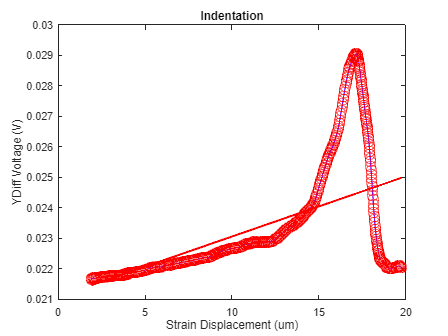

plot(smooth_Strain(minIndex:-1:1),fittedcurve,'r','LineWidth',2)
hold off

title('Indentation')
xlabel('Strain Displacement (um)')
ylabel('YDiff Voltage (V)')


slope = coeff(1)

slope = 1.9727e-04


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Displacement Conversion of Y-axis and Unit Conversion
Height = smooth_Strain * 0.000001

Height = 1.0e-04 *

    0.1975
    0.1973
    0.1972
    0.1970
    0.1968
    0.1967
    0.1965
    0.1963
    0.1962
    0.1960


Deflection = (smooth_Ydiff/slope)*0.000001

Deflection = 1.0e-03 *

    0.1117
    0.1117
    0.1118
    0.1118
    0.1118
    0.1119
    0.1120
    0.1120
    0.1120
    0.1120


Indentation = Height - Deflection

Indentation = 1.0e-03 *

   -0.0919
   -0.0920
   -0.0921
   -0.0921
   -0.0921
   -0.0922
   -0.0923
   -0.0923
   -0.0924
   -0.0924


%Convert Deflection into Force
Force = Deflection * SpringConst

Force = 1.0e-04 *

    0.3574
    0.3575
    0.3578
    0.3579
    0.3578
    0.3579
    0.3584
    0.3583
    0.3584
    0.3583



%Identify Point of Contact
